# Capítulo 4. Operaciones básicas con señales

### Resultado de aprendizaje

Al finalizar este capítulo, el estudiante será capaz de aplicar operaciones básicas sobre señales continuas y discretas, incluyendo desplazamiento, escalamiento temporal, reflexión, escalamiento de amplitud, suma, resta y multiplicación, interpretando sus efectos mediante representaciones gráficas en MATLAB Live Script.

### 4.1 Introducción

Las operaciones con señales permiten modificar su posición temporal, su duración, su orientación, su amplitud o su forma. Estas operaciones son esenciales para analizar sistemas, estudiar respuestas temporales, construir señales más complejas y comprender procesos como modulación, filtrado, retardo, inversión temporal y superposición.

En ingeniería, estas transformaciones aparecen en:

- Retardo de señales en canales de comunicación.

- Amplificación o atenuación de señales eléctricas.

- Compresión o expansión temporal en procesamiento de audio.

- Combinación de señales en sistemas de telecomunicaciones.

- Modelado de entradas y salidas en sistemas dinámicos.

En este capítulo se estudian las siguientes operaciones:

- Desplazamiento temporal.

- Escalamiento temporal.

- Reflexión temporal.

- Escalamiento de amplitud.

- Suma y resta de señales.

- Multiplicación de señales.

- Composición de operaciones.

## 4.2 Señal base para el análisis

Para estudiar las operaciones básicas, primero se define una señal base. En este caso se usará una señal sinusoidal amortiguada:

x(t) = e^(-t) sin(2*pi*f*t) u(t)

Esta señal permite observar con claridad los efectos de desplazamiento, escalamiento y modificación de amplitud.

## Ejemplo 1: Definición de una señal base continua

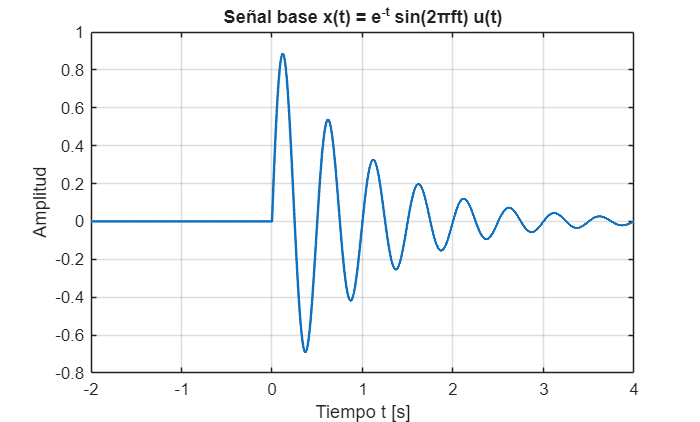

clc;
clear;
close all;

% Vector de tiempo
t = -2:0.001:4;

% Escalón unitario
u = double(t >= 0);

% Señal base
f = 2;
x = exp(-t).*sin(2*pi*f*t).*u;

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Señal base x(t) = e^{-t} sin(2πft) u(t)');

## Interpretación del Ejemplo 1

La señal base inicia en t = 0 debido al escalón unitario. Su amplitud disminuye con el tiempo por efecto del término exponencial e^(-t), mientras que la componente sinusoidal produce oscilaciones.

## 4.3 Desplazamiento temporal

El desplazamiento temporal consiste en mover una señal hacia la derecha o hacia la izquierda en el eje del tiempo.

Si se tiene x(t - t0), la señal se retrasa t0 unidades de tiempo.

Si se tiene x(t + t0), la señal se adelanta t0 unidades de tiempo.

En ingeniería, el retardo temporal aparece en canales de comunicación, propagación de ondas, transmisión de datos, sensores y sistemas de control.

## Ejemplo 2: Retardo temporal de una señal continua

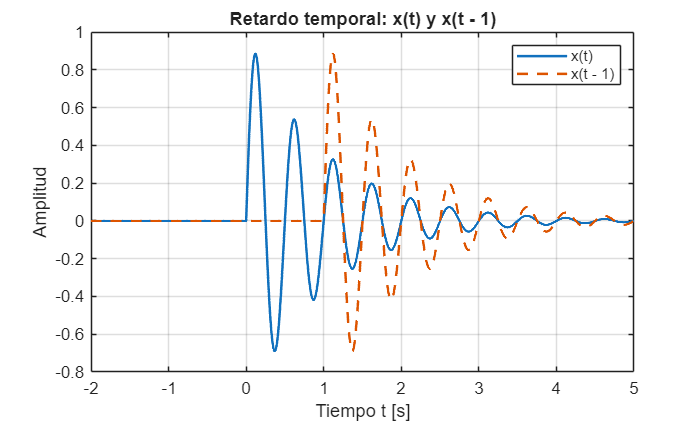

clc;
clear;
close all;

t = -2:0.001:5;
f = 2;

% Señal original
u_original = double(t >= 0);
x_original = exp(-t).*sin(2*pi*f*t).*u_original;

% Señal retardada: x(t - 1)
tau = 1;
t_shift = t - tau;
u_retardo = double(t_shift >= 0);
x_retardada = exp(-t_shift).*sin(2*pi*f*t_shift).*u_retardo;

% Gráfica
figure;
plot(t, x_original, 'LineWidth', 1.5);
hold on;
plot(t, x_retardada, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Retardo temporal: x(t) y x(t - 1)');
legend('x(t)', 'x(t - 1)');

## Ejemplo 3: Adelanto temporal de una señal continua

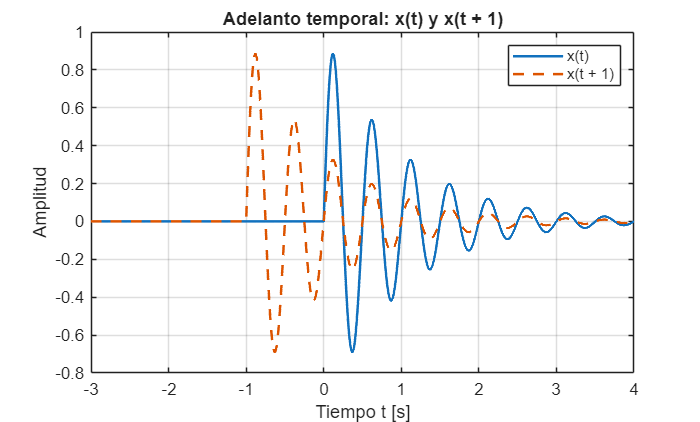

clc;
clear;
close all;

t = -3:0.001:4;
f = 2;

% Señal original
u_original = double(t >= 0);
x_original = exp(-t).*sin(2*pi*f*t).*u_original;

% Señal adelantada: x(t + 1)
tau = 1;
t_shift = t + tau;
u_adelanto = double(t_shift >= 0);
x_adelantada = exp(-t_shift).*sin(2*pi*f*t_shift).*u_adelanto;

% Gráfica
figure;
plot(t, x_original, 'LineWidth', 1.5);
hold on;
plot(t, x_adelantada, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Adelanto temporal: x(t) y x(t + 1)');
legend('x(t)', 'x(t + 1)');

## Interpretación del desplazamiento temporal

El retardo x(t - 1) desplaza la señal hacia la derecha, por lo que el evento inicia más tarde. El adelanto x(t + 1) desplaza la señal hacia la izquierda, por lo que el evento ocurre antes.

Esta operación es clave en telecomunicaciones, donde una señal puede llegar retardada al receptor debido a la propagación por un canal físico.

## 4.4 Escalamiento temporal

El escalamiento temporal modifica la duración de una señal.

Si se tiene x(a t):

- Si `a` > 1, la señal se comprime en el tiempo.

- Si 0 < |a| < 1, la señal se expande en el tiempo.

Esta operación es importante en procesamiento de audio, análisis de señales, comunicaciones y sistemas de radar.

## Ejemplo 4: Compresión temporal

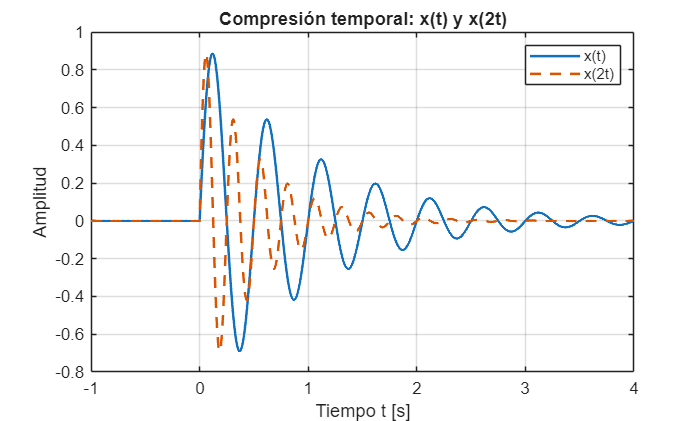

clc;
clear;
close all;

t = -1:0.001:4;
f = 2;

% Señal original
u_original = double(t >= 0);
x_original = exp(-t).*sin(2*pi*f*t).*u_original;

% Señal comprimida: x(2t)
a = 2;
t_scaled = a*t;
u_comp = double(t_scaled >= 0);
x_comprimida = exp(-t_scaled).*sin(2*pi*f*t_scaled).*u_comp;

figure;
plot(t, x_original, 'LineWidth', 1.5);
hold on;
plot(t, x_comprimida, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Compresión temporal: x(t) y x(2t)');
legend('x(t)', 'x(2t)');

## Ejemplo 5: Expansión temporal

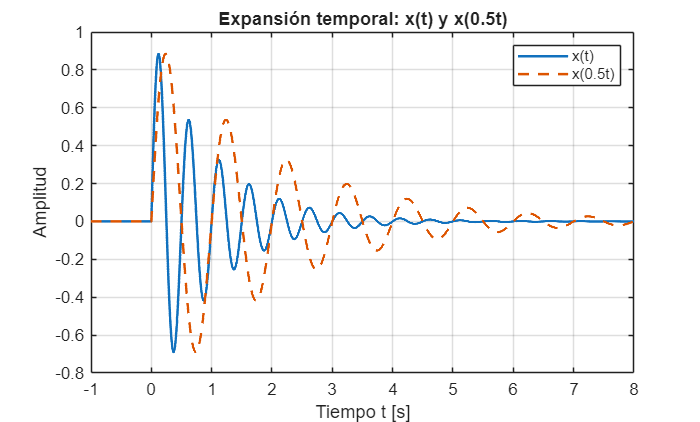

clc;
clear;
close all;

t = -1:0.001:8;
f = 2;

% Señal original
u_original = double(t >= 0);
x_original = exp(-t).*sin(2*pi*f*t).*u_original;

% Señal expandida: x(0.5t)
a = 0.5;
t_scaled = a*t;
u_exp = double(t_scaled >= 0);
x_expandida = exp(-t_scaled).*sin(2*pi*f*t_scaled).*u_exp;

figure;
plot(t, x_original, 'LineWidth', 1.5);
hold on;
plot(t, x_expandida, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Expansión temporal: x(t) y x(0.5t)');
legend('x(t)', 'x(0.5t)');

## Interpretación del escalamiento temporal

En la compresión temporal, la señal ocurre más rápido. En la expansión temporal, la señal se extiende y sus variaciones ocurren más lentamente.

En audio, una operación similar puede relacionarse con acelerar o ralentizar una señal. En comunicaciones, el escalamiento puede aparecer en análisis de pulsos y señales moduladas.

## 4.5 Reflexión temporal

La reflexión temporal invierte una señal respecto al eje vertical del tiempo. Se representa como x(-t).

Esta operación es fundamental para comprender gráficamente la convolución, ya que el procedimiento de convolución incluye la inversión temporal de una de las señales.

## Ejemplo 6: Reflexión temporal

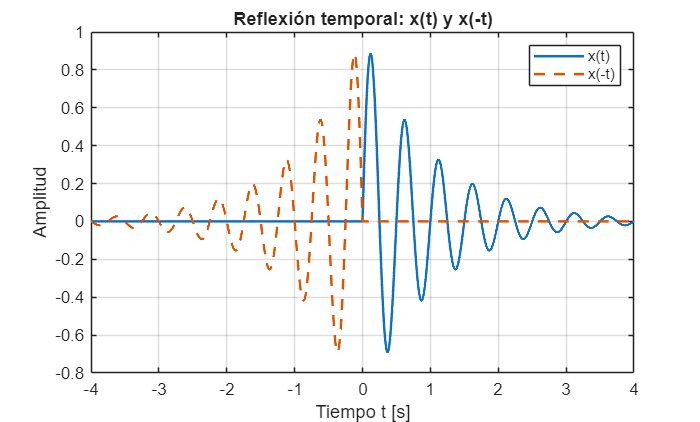

clc;
clear;
close all;

t = -4:0.001:4;
f = 2;

% Señal original
u_original = double(t >= 0);
x_original = exp(-t).*sin(2*pi*f*t).*u_original;

% Señal reflejada: x(-t)
t_ref = -t;
u_ref = double(t_ref >= 0);
x_reflejada = exp(-t_ref).*sin(2*pi*f*t_ref).*u_ref;

figure;
plot(t, x_original, 'LineWidth', 1.5);
hold on;
plot(t, x_reflejada, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Reflexión temporal: x(t) y x(-t)');
legend('x(t)', 'x(-t)');

## Interpretación de la reflexión temporal

La señal x(-t) invierte el comportamiento temporal de x(t). Lo que en la señal original ocurre para tiempos positivos, en la señal reflejada aparece para tiempos negativos.

Esta operación será especialmente importante al estudiar la convolución continua y discreta.

## 4.6 Escalamiento de amplitud

El escalamiento de amplitud consiste en multiplicar una señal por una constante:

y(t) = A x(t)

Si `A` > 1, la señal se amplifica.

Si 0 < |A| < 1, la señal se atenúa.

Si A < 0, además de cambiar su amplitud, la señal se invierte respecto al eje horizontal.

## Ejemplo 7: Amplificación y atenuación

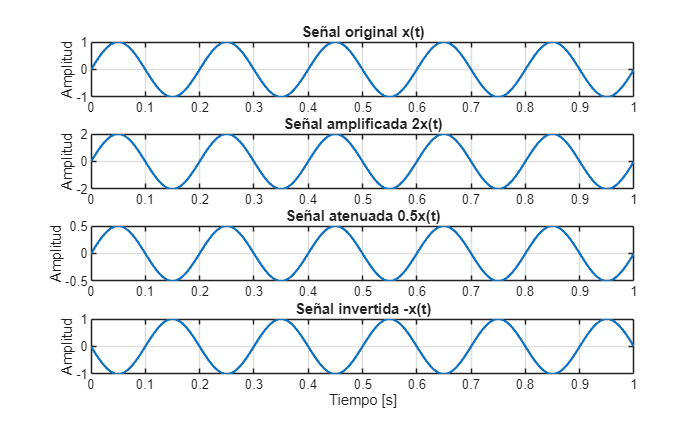

clc;
clear;
close all;

t = 0:0.001:1;
x = sin(2*pi*5*t);

% Escalamiento de amplitud
y_amplificada = 2*x;
y_atenuada = 0.5*x;
y_invertida = -x;

figure;

subplot(4,1,1);
plot(t, x, 'LineWidth', 1.4);
grid on;
title('Señal original x(t)');
ylabel('Amplitud');

subplot(4,1,2);
plot(t, y_amplificada, 'LineWidth', 1.4);
grid on;
title('Señal amplificada 2x(t)');
ylabel('Amplitud');

subplot(4,1,3);
plot(t, y_atenuada, 'LineWidth', 1.4);
grid on;
title('Señal atenuada 0.5x(t)');
ylabel('Amplitud');

subplot(4,1,4);
plot(t, y_invertida, 'LineWidth', 1.4);
grid on;
title('Señal invertida -x(t)');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## Aplicación del escalamiento de amplitud

El escalamiento de amplitud aparece en amplificadores, atenuadores, normalización de señales, control de volumen, ganancia de sensores y procesamiento digital.

En telecomunicaciones, la ganancia de un amplificador puede representarse mediante una multiplicación de la señal de entrada por una constante.

## 4.7 Suma y resta de señales

La suma de señales permite combinar información proveniente de diferentes fuentes. La resta permite comparar señales o eliminar componentes.

Si x1(t) y x2(t) son dos señales, entonces:

y(t) = x1(t) + x2(t)

z(t) = x1(t) - x2(t)

En aplicaciones reales, una señal recibida puede modelarse como la suma de una señal útil más ruido.

## Ejemplo 8: Suma de dos señales sinusoidales

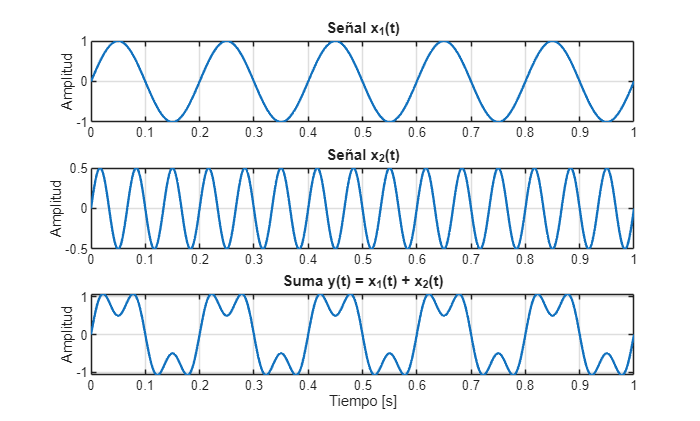

clc;
clear;
close all;

t = 0:0.001:1;

x1 = sin(2*pi*5*t);
x2 = 0.5*sin(2*pi*15*t);
y = x1 + x2;

figure;

subplot(3,1,1);
plot(t, x1, 'LineWidth', 1.4);
grid on;
title('Señal x_1(t)');
ylabel('Amplitud');

subplot(3,1,2);
plot(t, x2, 'LineWidth', 1.4);
grid on;
title('Señal x_2(t)');
ylabel('Amplitud');

subplot(3,1,3);
plot(t, y, 'LineWidth', 1.4);
grid on;
title('Suma y(t) = x_1(t) + x_2(t)');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## Ejemplo 9: Señal útil más ruido

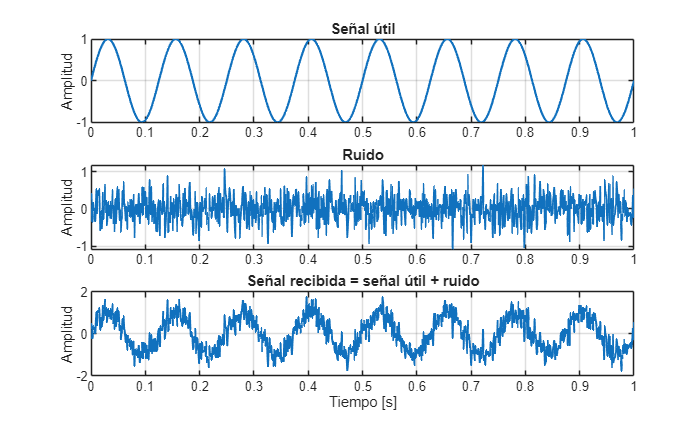

clc;
clear;
close all;

t = 0:0.001:1;

% Señal útil
senal_util = sin(2*pi*8*t);

% Ruido aleatorio
ruido = 0.35*randn(size(t));

% Señal recibida
senal_recibida = senal_util + ruido;

figure;

subplot(3,1,1);
plot(t, senal_util, 'LineWidth', 1.3);
grid on;
title('Señal útil');
ylabel('Amplitud');

subplot(3,1,2);
plot(t, ruido, 'LineWidth', 1.1);
grid on;
title('Ruido');
ylabel('Amplitud');

subplot(3,1,3);
plot(t, senal_recibida, 'LineWidth', 1.2);
grid on;
title('Señal recibida = señal útil + ruido');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## Interpretación de la suma de señales

La señal resultante contiene componentes de ambas señales originales. En el caso de señal útil más ruido, la información deseada queda mezclada con una componente aleatoria.

Este modelo es fundamental en telecomunicaciones, donde el receptor debe recuperar la señal útil a pesar de interferencias y ruido.

## 4.8 Multiplicación de señales

La multiplicación punto a punto de señales permite modificar una señal en función de otra. Esta operación aparece en modulación, enventanado, filtrado temporal y análisis de señales.

Si se tienen x1(t) y x2(t):

y(t) = x1(t) x2(t)

En modulación de amplitud, por ejemplo, una señal de información puede multiplicarse por una portadora sinusoidal.

## Ejemplo 10: Multiplicación de señales

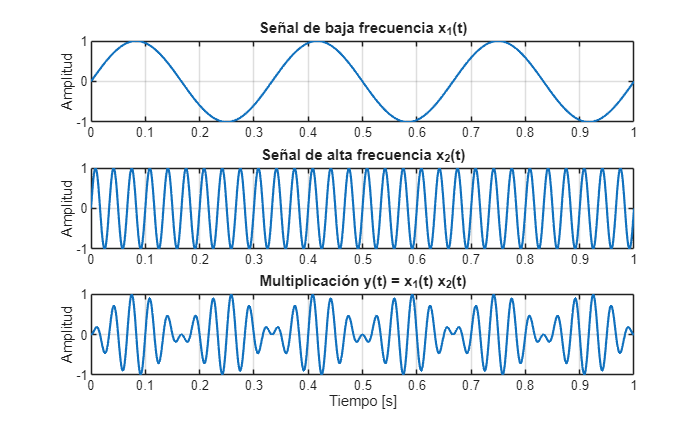

clc;
clear;
close all;

t = 0:0.001:1;

% Señal de baja frecuencia
x1 = sin(2*pi*3*t);

% Señal de alta frecuencia
x2 = sin(2*pi*30*t);

% Multiplicación
y = x1 .* x2;

figure;

subplot(3,1,1);
plot(t, x1, 'LineWidth', 1.3);
grid on;
title('Señal de baja frecuencia x_1(t)');
ylabel('Amplitud');

subplot(3,1,2);
plot(t, x2, 'LineWidth', 1.3);
grid on;
title('Señal de alta frecuencia x_2(t)');
ylabel('Amplitud');

subplot(3,1,3);
plot(t, y, 'LineWidth', 1.3);
grid on;
title('Multiplicación y(t) = x_1(t) x_2(t)');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## Ejemplo 11: Modulación de amplitud básica

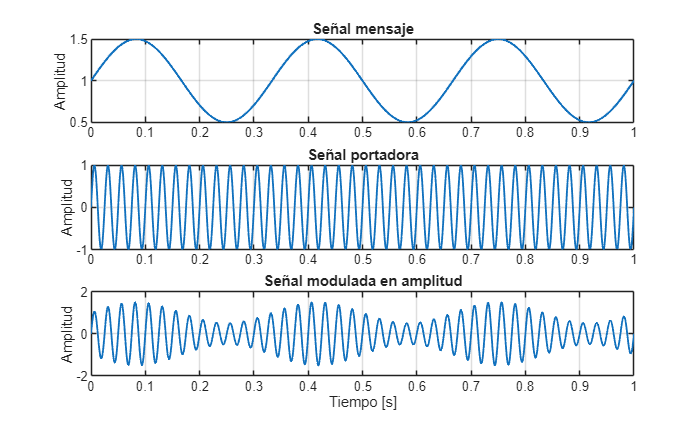

clc;
clear;
close all;

t = 0:0.0005:1;

% Mensaje
fm = 3;
mensaje = 1 + 0.5*sin(2*pi*fm*t);

% Portadora
fc = 40;
portadora = sin(2*pi*fc*t);

% Señal modulada
senal_modulada = mensaje .* portadora;

figure;

subplot(3,1,1);
plot(t, mensaje, 'LineWidth', 1.3);
grid on;
title('Señal mensaje');
ylabel('Amplitud');

subplot(3,1,2);
plot(t, portadora, 'LineWidth', 1.1);
grid on;
title('Señal portadora');
ylabel('Amplitud');

subplot(3,1,3);
plot(t, senal_modulada, 'LineWidth', 1.1);
grid on;
title('Señal modulada en amplitud');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## Interpretación de la multiplicación

En el ejemplo de modulación, la amplitud de la portadora cambia siguiendo la forma de la señal mensaje. Esta operación es una base conceptual para entender algunos sistemas de comunicación analógica.

Aunque aquí se muestra un caso básico, la multiplicación de señales también aparece en técnicas modernas de procesamiento y comunicaciones digitales.

## 4.9 Operaciones con señales discretas

Las operaciones de desplazamiento, escalamiento de amplitud, suma y multiplicación también pueden aplicarse a señales discretas.

En señales discretas, el desplazamiento se realiza sobre el índice n. Por ejemplo, x[n - 2] representa una señal retardada dos muestras.

## Ejemplo 12: Desplazamiento de una señal discreta

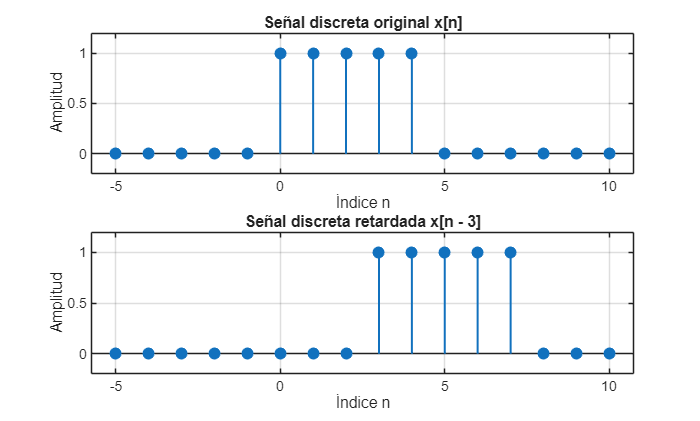

clc;
clear;
close all;

n = -5:10;

% Señal discreta original
x = double(n >= 0) - double(n >= 5);

% Señal retardada
n0 = 3;
x_retardada = double((n - n0) >= 0) - double((n - n0) >= 5);

figure;

subplot(2,1,1);
stem(n, x, 'filled', 'LineWidth', 1.2);
grid on;
title('Señal discreta original x[n]');
xlabel('Índice n');
ylabel('Amplitud');
ylim([-0.2 1.2]);

subplot(2,1,2);
stem(n, x_retardada, 'filled', 'LineWidth', 1.2);
grid on;
title('Señal discreta retardada x[n - 3]');
xlabel('Índice n');
ylabel('Amplitud');
ylim([-0.2 1.2]);

## Ejemplo 13: Suma de señales discretas

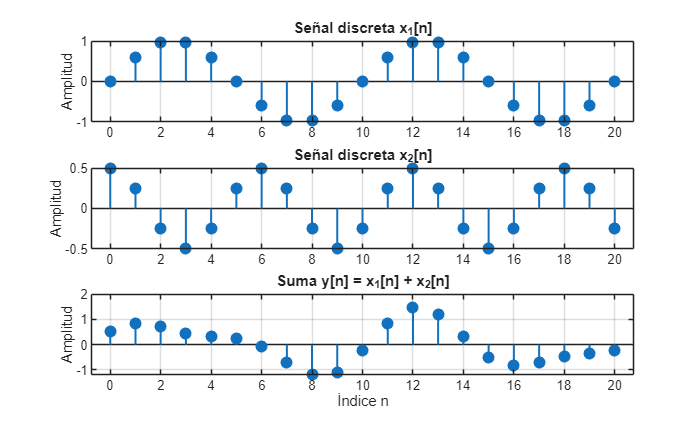

clc;
clear;
close all;

n = 0:20;

x1 = sin(pi*n/5);
x2 = 0.5*cos(pi*n/3);
y = x1 + x2;

figure;

subplot(3,1,1);
stem(n, x1, 'filled', 'LineWidth', 1.2);
grid on;
title('Señal discreta x_1[n]');
ylabel('Amplitud');

subplot(3,1,2);
stem(n, x2, 'filled', 'LineWidth', 1.2);
grid on;
title('Señal discreta x_2[n]');
ylabel('Amplitud');

subplot(3,1,3);
stem(n, y, 'filled', 'LineWidth', 1.2);
grid on;
title('Suma y[n] = x_1[n] + x_2[n]');
xlabel('Índice n');
ylabel('Amplitud');

## 4.10 Composición de operaciones

En muchos problemas reales, se aplican varias operaciones de forma simultánea. Por ejemplo:

y(t) = 2 x(3t - 1)

Esta expresión combina:

- Escalamiento de amplitud por 2.

- Escalamiento temporal por 3.

- Desplazamiento temporal.

Para interpretar correctamente una composición de operaciones, conviene analizar primero lo que ocurre dentro del argumento de la señal.

## Ejemplo 14: Composición de operaciones

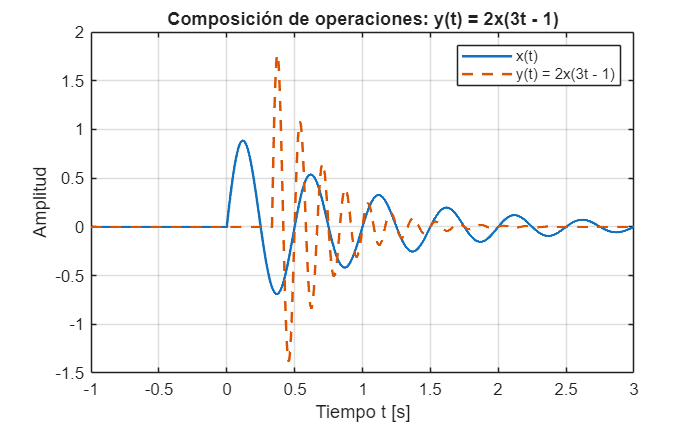

clc;
clear;
close all;

t = -1:0.001:3;
f = 2;

% Señal original
u_original = double(t >= 0);
x_original = exp(-t).*sin(2*pi*f*t).*u_original;

% Señal transformada y(t) = 2 x(3t - 1)
argumento = 3*t - 1;
u_arg = double(argumento >= 0);
y = 2*exp(-argumento).*sin(2*pi*f*argumento).*u_arg;

figure;
plot(t, x_original, 'LineWidth', 1.5);
hold on;
plot(t, y, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Composición de operaciones: y(t) = 2x(3t - 1)');
legend('x(t)', 'y(t) = 2x(3t - 1)');

## Interpretación de la composición

La señal transformada presenta cambios simultáneos en amplitud, duración y posición temporal. Este tipo de análisis es importante para comprender cómo los sistemas modifican las señales de entrada.

En ingeniería, una señal puede ser amplificada, retardada y comprimida como resultado de pasar por diferentes etapas de procesamiento.

## 4.11 Aplicación en telecomunicaciones

Las operaciones con señales son fundamentales en telecomunicaciones:

- El desplazamiento temporal modela retardos de propagación.

- El escalamiento de amplitud modela ganancia o atenuación.

- La suma de señales modela interferencia y ruido.

- La multiplicación de señales aparece en modulación.

- La reflexión temporal se usa en el análisis gráfico de convolución.

Estas operaciones permiten describir matemáticamente cómo una señal cambia al propagarse por un canal o al ser procesada por un sistema.

## Ejemplo 15: Canal simple con atenuación, retardo y ruido

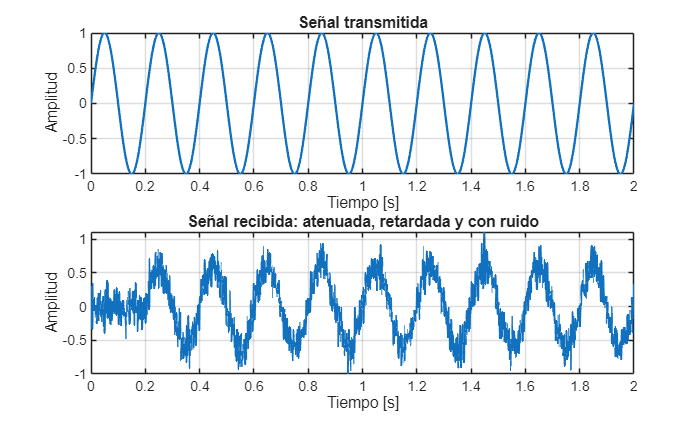

clc;
clear;
close all;

t = 0:0.001:2;

% Señal transmitida
x = sin(2*pi*5*t);

% Retardo aproximado
retardo = 0.2;
t_ret = t - retardo;
x_ret = sin(2*pi*5*t_ret);
x_ret(t_ret < 0) = 0;

% Atenuación
atenuacion = 0.6;

% Ruido
ruido = 0.15*randn(size(t));

% Señal recibida
y = atenuacion*x_ret + ruido;

figure;

subplot(2,1,1);
plot(t, x, 'LineWidth', 1.4);
grid on;
title('Señal transmitida');
xlabel('Tiempo [s]');
ylabel('Amplitud');

subplot(2,1,2);
plot(t, y, 'LineWidth', 1.2);
grid on;
title('Señal recibida: atenuada, retardada y con ruido');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## Interpretación del canal simple

La señal recibida es una versión modificada de la señal transmitida. El canal introduce retardo, atenuación y ruido. Este modelo básico permite comprender problemas reales de transmisión de información.

Aunque el ejemplo es simplificado, representa una idea central en telecomunicaciones: la señal recibida rara vez es idéntica a la señal transmitida.

## Actividades propuestas

1. Genere una señal sinusoidal y aplique un retardo de 0.5 segundos. 

2. Genere una señal sinusoidal y aplique un adelanto de 0.3 segundos. 

3. Compare gráficamente x(t), x(2t) y x(0.5t). 

4. Grafique x(t) y x(-t) para una señal rampa limitada. 

5. Aplique ganancias de 0.5, 2 y -1 a una señal y explique los resultados. 

6. Sume dos señales sinusoidales con diferentes frecuencias. 

7. Simule una señal útil contaminada con ruido aleatorio. 

8. Multiplique una señal de baja frecuencia por una portadora de alta frecuencia. 

9. En señales discretas, grafique x[n], x[n - 2] y x[n + 2]. 

10. Proponga un ejemplo de canal de comunicación que incluya retardo, atenuación y ruido.

### Preguntas de reflexión

1. ¿Qué diferencia existe entre un retardo y un adelanto temporal? 

2. ¿Qué ocurre cuando una señal se evalúa como x(2t)? 

3. ¿Por qué la reflexión temporal es importante para estudiar convolución? 

4. ¿Qué representa físicamente multiplicar una señal por una constante? 

5. ¿Por qué una señal recibida puede modelarse como suma de señal útil y ruido?

### Conclusiones

Las operaciones básicas con señales permiten modificar su forma, posición, duración y amplitud. Estas transformaciones son necesarias para analizar el comportamiento de señales en sistemas reales.

El desplazamiento temporal representa retardos o adelantos; el escalamiento temporal produce compresión o expansión; la reflexión invierte la señal en el tiempo; el escalamiento de amplitud representa ganancia o atenuación; y la suma y multiplicación permiten modelar interferencia, ruido y modulación.

MATLAB Live Script facilita la comprensión de estas operaciones porque permite visualizar de manera directa el efecto de cada transformación sobre una señal.

### Bibliografía básica

- Oppenheim, A. V., Willsky, A. S., & Nawab, S. H. Señales y sistemas.

- Lathi, B. P. Linear Systems and Signals.

- Haykin, S., & Van Veen, B. Signals and Systems.

- Proakis, J. G., & Manolakis, D. G. Digital Signal Processing.

- MathWorks Documentation. MATLAB Live Editor.